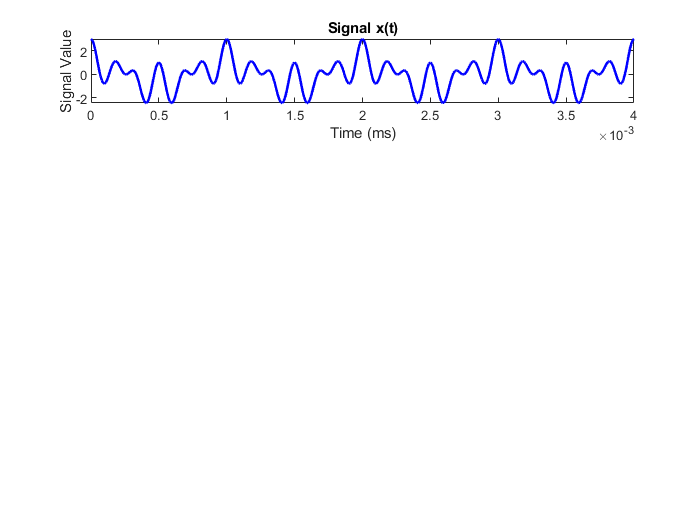

% 1-6

clc
clear all;
% Creating the main signal as smooth as possible to seem continious 
t = 0:1/100000:4/1000;  
f1 = 4*10e2;  
f2 = 1*10e2;  
f3 = 6*10e2;  

x = cos(2*pi*f1*t) + cos(2*pi*f2*t) + cos(2*pi*f3*t);  % Signal x(t)

subplot(4,1,1)
plot(t, x, 'b' ,'LineWidth',1.5);
xlabel('Time (ms)');
ylabel('Signal Value');
title('Signal x(t)');

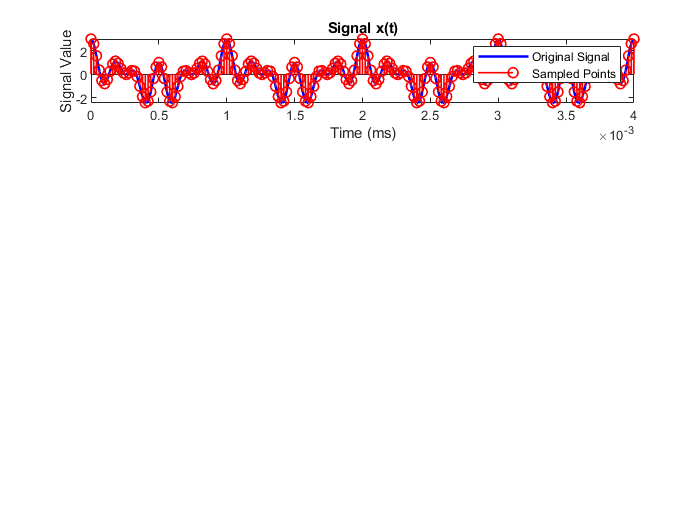

% Sampling Process

fsample = 5*10e3;  
Ts = 1/fsample;  
t_sampled = 0:Ts:4/1000;  
x_sampled = cos(2*pi*f1*t_sampled) + cos(2*pi*f2*t_sampled) + cos(2*pi*f3*t_sampled);  % Sampled signal

hold on;
stem(t_sampled, x_sampled, 'ro', 'LineWidth',1);
legend('Original Signal', 'Sampled Points');
hold off;

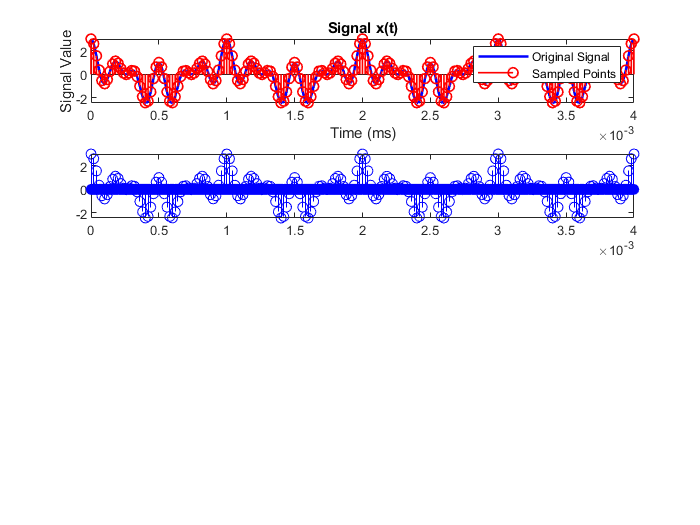

%Interpolation
prc_rate = 10;
t1 = -4/1000:1 / (prc_rate * fsample):4/1000;
x1 = zeros(1, (length(t1) + 1) / 2);
x1(1:prc_rate:end) = x_sampled;
subplot(4,1,2);
stem(t1((length(t1) + 1) / 2:end),x1,'b');

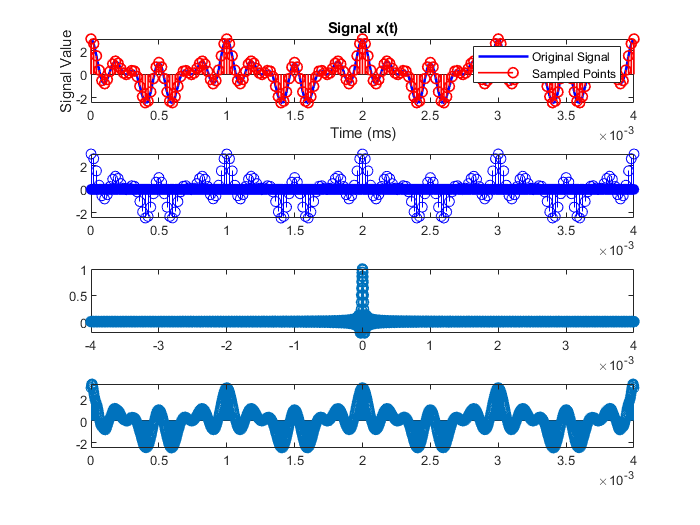

%Filtering with Ideal filter
% Question1
% The result would be a signal similar to the main signal as we see...


h = sinc(fsample * t1); %Ideal filter
subplot(4,1,3);
stem(t1,h,'LineWidth',1);

y = conv(x1, h, 'same'); % Passing through the filter
subplot(4,1,4)
stem(t1((length(t1) + 1) / 2:end), y);

% Question2
% Increasing the length of the filter reconstruct the sampled signal more
% similar to the main signal.

%1_7
% Creating signal
clc
clear
fs=100;
t = -5 : 1/fs : 5;
x = (sinc(5 * t)).^2;
N = length(x);
f_axis = linspace(-fs / 2, fs / 2, N);
FT_x = fftshift(fft(x))/fs;


% Sampling at 4 Hz
sampling_frq1 = 4;
sampled_signal1 = zeros(1, N);
sampled_signal1(1:fs/sampling_frq1:end) = x(1:fs/sampling_frq1:end);
FT_sampled_signal1 = 1 / sampling_frq1 * fftshift(fft(sampled_signal1));

% Sampling at 5 Hz
sampling_frq2 = 5;
sampled_signal2 = zeros(1, N);
sampled_signal2(1:fs/sampling_frq2:end) = x(1:fs/sampling_frq2:end);
FT_sampled_signal2 = 1 / sampling_frq2 * fftshift(fft(sampled_signal2));

% Sampling at 10 Hz
sampling_frq3 = 10;
sampled_signal3 = zeros(1, N);
sampled_signal3(1:fs/sampling_frq3:end) = x(1:fs/sampling_frq3:end);
FT_sampled_signal3 = 1 / sampling_frq3 * fftshift(fft(sampled_signal3));

% Sampling at 20 Hz
sampling_frq4 = 20;
sampled_signal4 = zeros(1, N);
sampled_signal4(1:fs/sampling_frq4:end) = x(1:fs/sampling_frq4:end);
FT_sampled_signal4 = 1 / sampling_frq4 * fftshift(fft(sampled_signal4));

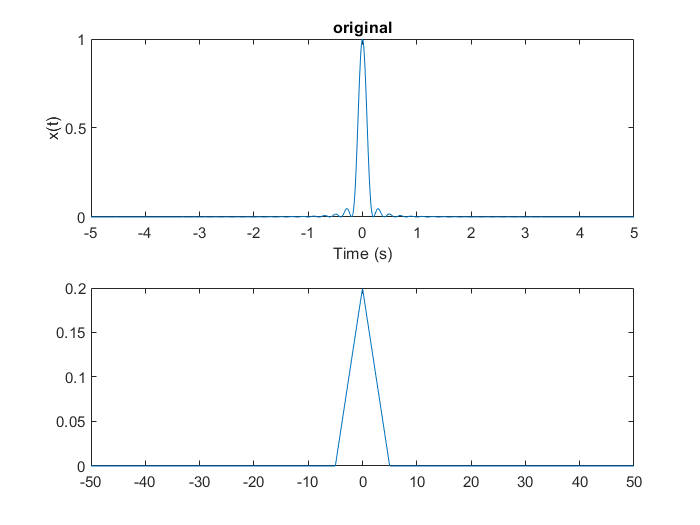

% Plotting the sampled signals
figure
subplot(2,1,1);
plot(t, x,'LineWidth',0.5);
xlabel('Time (s)');
ylabel('x(t)');
title('original');
subplot(2,1,2);
plot(f_axis, abs(FT_x));

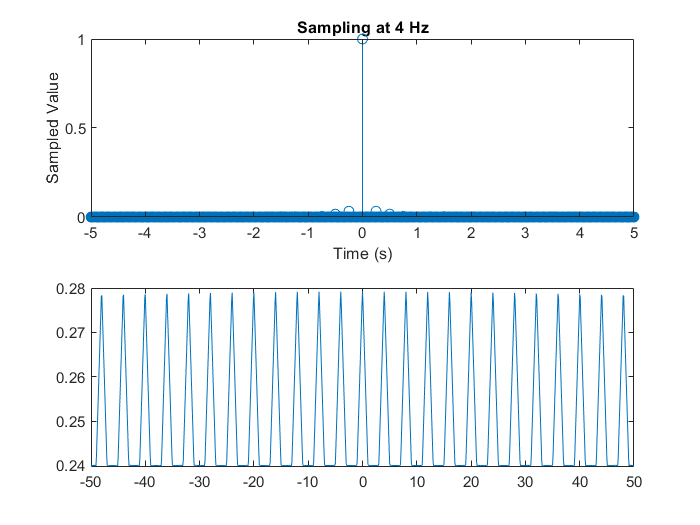



figure
subplot(2,1,1);
stem(t, sampled_signal1,'LineWidth',0.2);
xlabel('Time (s)');
ylabel('Sampled Value');
title('Sampling at 4 Hz');
subplot(2,1,2);
plot(f_axis, abs(FT_sampled_signal1));

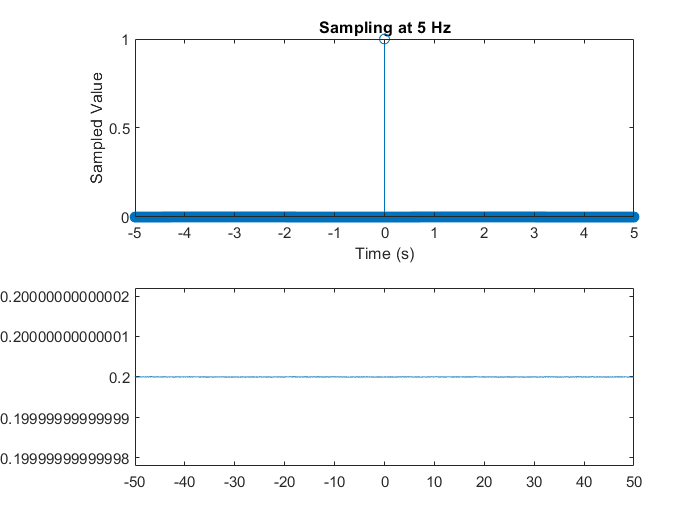


figure
subplot(2,1,1);
stem(t, sampled_signal2);
xlabel('Time (s)');
ylabel('Sampled Value');
title('Sampling at 5 Hz');
subplot(2,1,2);
plot(f_axis, abs(FT_sampled_signal2));

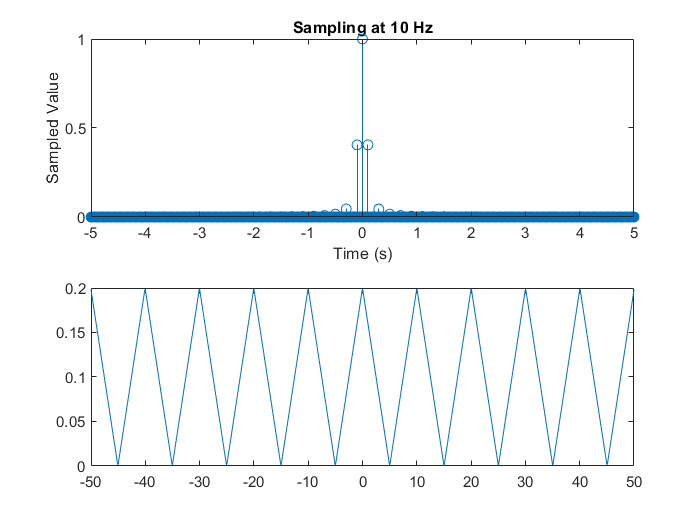



figure
subplot(2,1,1);
stem(t, sampled_signal3);
xlabel('Time (s)');
ylabel('Sampled Value');
title('Sampling at 10 Hz');
subplot(2,1,2);
plot(f_axis, abs(FT_sampled_signal3));

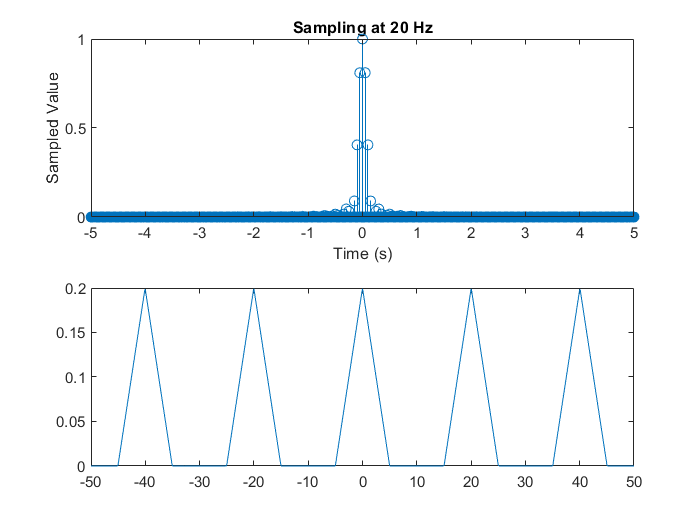



figure
subplot(2,1,1);
stem(t, sampled_signal4);
xlabel('Time (s)');
ylabel('Sampled Value');
title('Sampling at 20 Hz');
subplot(2,1,2);
plot(f_axis, abs(FT_sampled_signal4));

% Question3
% As we see, bandwidth of main signal is 5 kz so when the sampling rate is
% 5khz full aliasing happens that totally ruins the main signal.
% Thats also obvious that best sampling frequency is 10 khz and higher
% sampling frequencies will leave more space between the shifts of main
% signal
b

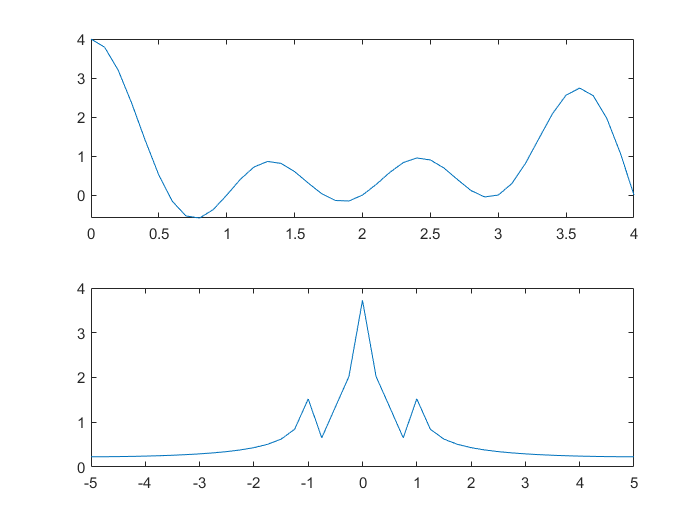

%1_9
clc
clear
fs = 10;
t = 0 : 1/fs : 4;

x = cos(2*pi*(1/16)*t)+cos(2*pi*(5/16)*t)+cos(2*pi*(9/16)*t)+cos(2*pi*(13/16)*t);
   
% Fourier transform of x
N = length(x);
f_axis = linspace(-fs / 2, fs / 2, N);
FT_x = fftshift(fft(x))/fs;
 figure;
subplot(2,1,1);
plot(t, x);
subplot(2,1,2);
plot(f_axis, abs(FT_x));


decomposition_coeffs =xlsread('C:\Users\kmnej\Downloads\filters.xls','Sheet1');
combination_coeffs =xlsread('C:\Users\kmnej\Downloads\filters.xls','Sheet2');


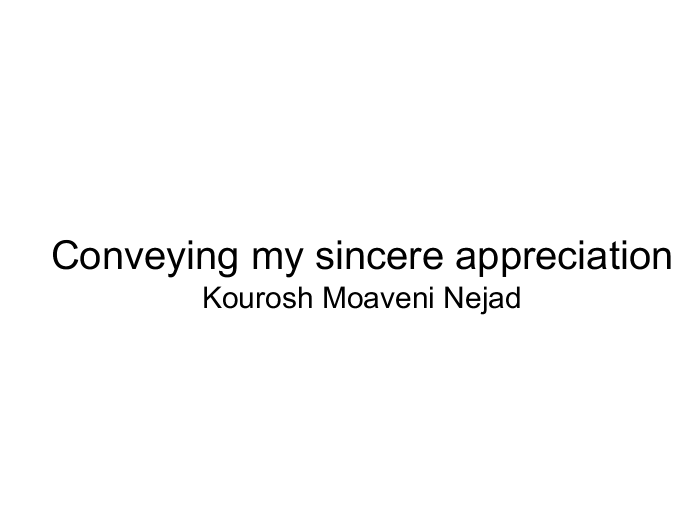


figure;
text(0.5, 0.5, 'Conveying my sincere appreciation', 'FontSize', 24, 'HorizontalAlignment', 'center');
text(0.5, 0.4, 'Kourosh Moaveni Nejad', 'FontSize', 18, 'HorizontalAlignment', 'center');

axis off;  
set(gcf, 'Color', 'white');  